# Logistic equation


$$\frac{dy}{dt} = ay - by^2$$


a = 6; b = 2;
K = a/b

K =      3


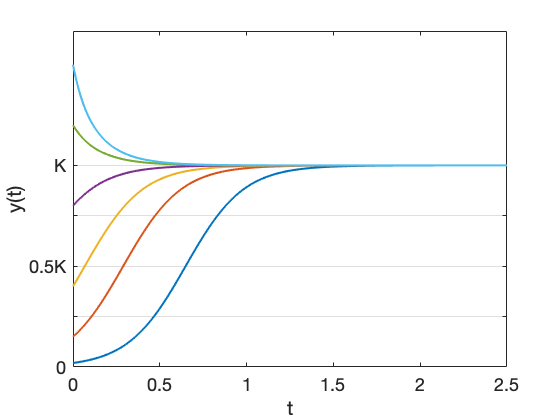

f = @(t,y) a*y - b*y^2;
t = linspace(0,2.5,300);
for y0 = K*[0.02 0.15 0.4 0.8 1.2 1.5]
    [t,y] = ode45(f,t,y0);
    plot(t,y), hold on
end
xlabel('t'), ylabel('y(t)')
set(gca,'ygrid','on',...
  'ytick',K*(0:.25:1),'yticklabel',{'0','','0.5K','','K'})